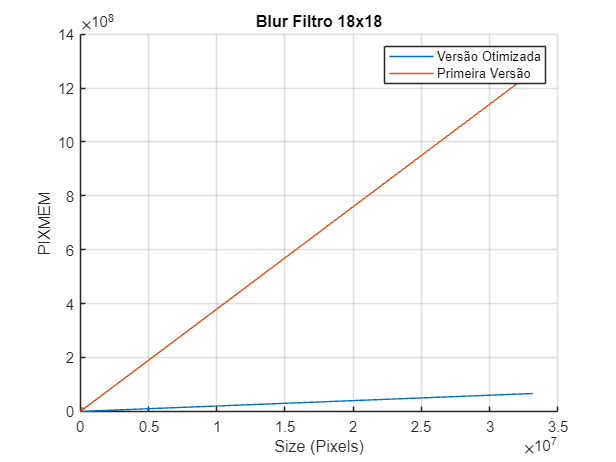

otimized_blur = fopen('optimized_blur.txt', 'r');

if otimized_blur == -1
    error('File cannot be opened');
end

fgetl(otimized_blur);  % Skip the first line
dataArray = textscan(otimized_blur, '%f %f', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(otimized_blur);

% Extracting columns
pixmemColumn = dataArray{1};  % First column
timeColumn = dataArray{2};   % Second column

%%%%%%%%%%%%%%%%%%%%%%%%% SIZE    %%%%%%%%%%%%%%%%%

sizeFile = fopen('sizes.txt','r');
if sizeFile == -1
    error('File cannot be opened');
end
fgetl(sizeFile);  % Skip the first line
dataArraySize = textscan(sizeFile, '%f','Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(sizeFile);
sizeColumn = dataArraySize{1};  % Size data

%%%%%%%%%%%%%%%%%%%%% BAD BLURRRRRRR %%%%%%%%%%%

bad_blur = fopen('bad_blur.txt', 'r');

if bad_blur == -1
    error('File cannot be opened');
end

fgetl(bad_blur);  % Skip the first line
dataArrayBad = textscan(bad_blur, '%f %f %f', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(bad_blur);

% Extracting columns
pixmemColumnBad = dataArrayBad{1};  % First column
timeColumnBad = dataArrayBad{2};   % Second column

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PLOT %%%%%%%%%

hold on;
grid on;
title("Blur Filtro 18x18");
xlabel("Size (Pixels)");
ylabel("PIXMEM");

plot(sizeColumn, pixmemColumn);
plot(sizeColumn, pixmemColumnBad);
legend('Versão Otimizada', 'Primeira Versão');  % Legenda após todas as plotagens
saveas(gcf,'blur.png');